# **MATLAB COVID-19 Data Analysis Challenge Part 2**

**Author: Juergen Kanz, Sep. 2020, **[https:\\about.me\juergenkanz](https:\\about.me\juergenkanz)

In this script, I go deeper into the data analysis. To run the script by yourself, please set-up a 'github' environment as described in **MATLAB COVID-19 Data Analysis Challenge Part 1, section 1. **

clearvars;close all;

## Load time series data

Please adapt the paths for filename1, filename2, filename3 in this section for your own needs. Be aware that we are working here with the time series.

% Load of the time series for confirmed cases
filename1='E:\Users\juerg\Documents\MATLAB\Projects\COVID19analysis\csse_covid_19_data\csse_covid_19_time_series\time_series_covid19_confirmed_global.csv';
confirmed=readtable(filename1,'TextType','string','ReadVariableNames',true,'PreserveVariableNames',true);
confirmed = renamevars(confirmed,["Country/Region","Province/State"],["Country","Province"])

confirmed = 266×255 table
               Province                      Country             Lat       Long      1/22/20    1/23/20    1/24/20    1/25/20    1/26/20    1/27/20    1/28/20    1/29/20    1/30/20    1/31/20    2/1/20    2/2/20    2/3/20    2/4/20    2/5/20    2/6/20    2/7/20    2/8/20    2/9/20    2/10/20    2/11/20    2/12/20    2/13/20    2/14/20    2/15/20    2/16/20    2/17/20    2/18/20    2/19/20    2/20/20


% Load of the time series for deaths cases
filename2='E:\Users\juerg\Documents\MATLAB\Projects\COVID19analysis\csse_covid_19_data\csse_covid_19_time_series\time_series_covid19_deaths_global.csv';
deaths=readtable(filename2,'TextType','string','ReadVariableNames',true,'PreserveVariableNames',true);
deaths = renamevars(deaths,["Country/Region","Province/State"],["Country","Province"])

deaths = 266×255 table
               Province                      Country             Lat       Long      1/22/20    1/23/20    1/24/20    1/25/20    1/26/20    1/27/20    1/28/20    1/29/20    1/30/20    1/31/20    2/1/20    2/2/20    2/3/20    2/4/20    2/5/20    2/6/20    2/7/20    2/8/20    2/9/20    2/10/20    2/11/20    2/12/20    2/13/20    2/14/20    2/15/20    2/16/20    2/17/20    2/18/20    2/19/20    2/20/20


% Load of the time series for recovered cases
filename3='E:\Users\juerg\Documents\MATLAB\Projects\COVID19analysis\csse_covid_19_data\csse_covid_19_time_series\time_series_covid19_recovered_global.csv';
recovered=readtable(filename3,'TextType','string','ReadVariableNames',true,'PreserveVariableNames',true);
recovered = renamevars(recovered,["Country/Region","Province/State"],["Country","Province"])

recovered = 253×255 table
               Province                      Country             Lat       Long      1/22/20    1/23/20    1/24/20    1/25/20    1/26/20    1/27/20    1/28/20    1/29/20    1/30/20    1/31/20    2/1/20    2/2/20    2/3/20    2/4/20    2/5/20    2/6/20    2/7/20    2/8/20    2/9/20    2/10/20    2/11/20    2/12/20    2/13/20    2/14/20    2/15/20    2/16/20    2/17/20    2/18/20    2/19/20    2/20/20

#### Data preparation for next steps

ncolumns=size(confirmed,2)

ncolumns = 255

names=confirmed.Properties.VariableNames;
lastday=(confirmed.Properties.VariableNames(length(names)))

lastday = 1×1 cell array
    {'9/28/20'}


times=names(5:ncolumns);
formatOut = 'mm/dd/yy';
times=datestr(times(:),formatOut);

## Calculate worldwide cases until yesterday

**Number of total infected and confirmed people**

totalConfirmed = sum(confirmed{:,lastday},1)

totalConfirmed = 33353615

**Number of people who passed away**

totalDeaths = sum(deaths{:,lastday},1)

totalDeaths = 1001646

**Number of recovered people**

totalRecovered = sum(recovered{:,lastday},1)

totalRecovered = 23151081

**Number of active cases**

totalActive= totalConfirmed-totalDeaths-totalRecovered

totalActive = 9200888

## Worldwide distribution

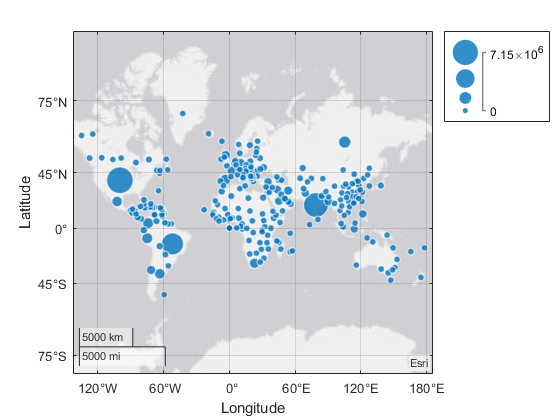

figure;
geobubble(confirmed.Lat,confirmed.Long,confirmed{:,lastday})

### The "Hottest" COVID19 countries on earth

***Confirmed Cases:***

confirmedhotcountry=sortrows(confirmed,lastday,'descend');
confirmedhotcountry2=confirmedhotcountry(:,[2 ncolumns])

confirmedhotcountry2 = 266×2 table
        Country          9/28/20  
    ________________    __________

    "US"                 7.148e+06
    "India"             6.1453e+06
    "Brazil"            4.7455e+06
    "Russia"            1.1543e+06
    "Colombia"           8.182e+05
    "Peru"               8.053e+05
    "Spain"             7.4827e+05
    "Mexico"            7.3372e+05
    "Argentina"         7.2313e+05
    "South Africa"      6.7167e+05
    "France"            5.5283e+05
    "Chile"             4.5967e+05
    "Iran"              4.4996e+05
    "United Kingdom"    4.3901e+05
    "Bangladesh"        3.6056e+05
    "Iraq"              3.5357e+05


***Number of Deaths:***

deathshotcountry=sortrows(deaths,lastday,'descend');
deathshotcountry2=deathshotcountry(:,[2 ncolumns])

deathshotcountry2 = 266×2 table
        Country          9/28/20  
    ________________    __________

    "US"                2.0507e+05
    "Brazil"            1.4206e+05
    "India"                  96318
    "Mexico"                 76603
    "United Kingdom"         42001
    "Italy"                  35851
    "Peru"                   32262
    "France"                 31549
    "Spain"                  31411
    "Iran"                   25779
    "Colombia"               25641
    "Russia"                 20299
    "South Africa"           16586
    "Argentina"              16113
    "Chile"                  12698
    "Ecuador"                11280


## Country specific analysis

% allcountries = unique(confirmed.Country);   
%  as input for selectedCountry Drop Down Menue

### Chose your country of interest

selectedCountry = "US"

selectedCountry = "US"

confirmedinCountry = confirmed(confirmed.Country == selectedCountry, :)

confirmedinCountry = 1×255 table
    Province     Country    Lat    Long    1/22/20    1/23/20    1/24/20    1/25/20    1/26/20    1/27/20    1/28/20    1/29/20    1/30/20    1/31/20    2/1/20    2/2/20    2/3/20    2/4/20    2/5/20    2/6/20    2/7/20    2/8/20    2/9/20    2/10/20    2/11/20    2/12/20    2/13/20    2/14/20    2/15/20    2/16/20    2/17/20    2/18/20    2/19/20    2/20/20    2/21/20 

deathsinCountry = deaths(deaths.Country == selectedCountry, :)

deathsinCountry = 1×255 table
    Province     Country    Lat    Long    1/22/20    1/23/20    1/24/20    1/25/20    1/26/20    1/27/20    1/28/20    1/29/20    1/30/20    1/31/20    2/1/20    2/2/20    2/3/20    2/4/20    2/5/20    2/6/20    2/7/20    2/8/20    2/9/20    2/10/20    2/11/20    2/12/20    2/13/20    2/14/20    2/15/20    2/16/20    2/17/20    2/18/20    2/19/20    2/20/20    2/21/20    

recoveredinCountry = recovered(recovered.Country == selectedCountry, :)

recoveredinCountry = 1×255 table
    Province     Country    Lat    Long    1/22/20    1/23/20    1/24/20    1/25/20    1/26/20    1/27/20    1/28/20    1/29/20    1/30/20    1/31/20    2/1/20    2/2/20    2/3/20    2/4/20    2/5/20    2/6/20    2/7/20    2/8/20    2/9/20    2/10/20    2/11/20    2/12/20    2/13/20    2/14/20    2/15/20    2/16/20    2/17/20    2/18/20    2/19/20    2/20/20    2/21/20 

confirmedinCountry{:,lastday}

ans = 7148045

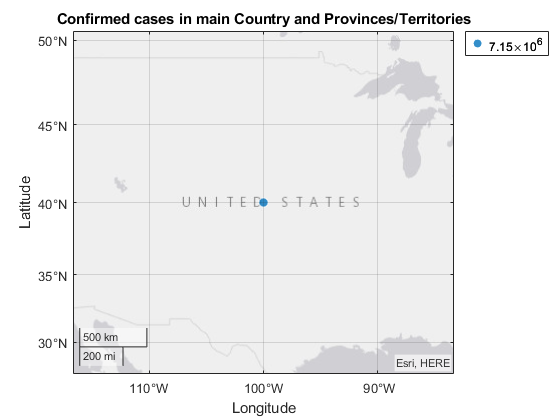


figure;
m=geobubble(confirmedinCountry.Lat,confirmedinCountry.Long,confirmedinCountry{:,lastday});
title('Confirmed cases in main Country and Provinces/Territories')

### Time dependent plots

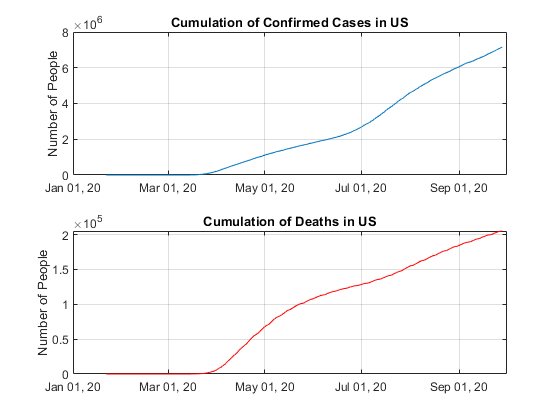

datconfSelectedCountry=sum(confirmedinCountry{:,5:ncolumns},1);
datdeathSelectedCountry=sum(deathsinCountry{:,5:ncolumns},1);
datrecovSelectedCountry=sum(recoveredinCountry{:,5:ncolumns},1);

% Calculation of daily new cases based on cumulated data
for i=2:length(datconfSelectedCountry)
  dataconfSelectedCountry(i)=datconfSelectedCountry(i)-datconfSelectedCountry(i-1);
  datadeathSelectedCountry(i)=datdeathSelectedCountry(i)-datdeathSelectedCountry(i-1);
  datarecovSelectedCountry(i)=datrecovSelectedCountry(i)-datrecovSelectedCountry(i-1);
end

tsconfSelectedCountry = timeseries(datconfSelectedCountry,times);
tsdeathSelectedCountry = timeseries(datdeathSelectedCountry,times);
tsrecovSelectedCountry = timeseries(datdeathSelectedCountry,times);
ts2confSelectedCountry = timeseries(dataconfSelectedCountry,times);
ts2deathSelectedCountry = timeseries(datadeathSelectedCountry,times);
ts2recovSelectedCountry = timeseries(datarecovSelectedCountry,times);



tsconfSelectedCountry.TimeInfo.Units = 'days';
ts2confSelectedCountry.TimeInfo.Units = 'days';
tsdeathSelectedCountry.TimeInfo.Units = 'days';
ts2deathSelectedCountry.TimeInfo.Units = 'days';
tsconfSelectedCountry.TimeInfo.Format = 'mmm dd, yy';                           % Set format for display on x-axis.
ts2confSelectedCountry.TimeInfo.Format = 'mmm dd, yy'; 
tsdeathSelectedCountry.TimeInfo.Format = 'mmm dd, yy';                          % Set format for display on x-axis.
ts2deathSelectedCountry.TimeInfo.Format = 'mmm dd, yy'; 
tsconfSelectedCountry.Time = tsconfSelectedCountry.Time - tsconfSelectedCountry.Time(1);        % Express time relative to the start date.
ts2confSelectedCountry.Time = ts2confSelectedCountry.Time - ts2confSelectedCountry.Time(1); 
tsdeathSelectedCountry.Time = tsdeathSelectedCountry.Time - tsdeathSelectedCountry.Time(1);     % Express time relative to the start date.
ts2confSelectedCountry.Time = ts2confSelectedCountry.Time - ts2deathSelectedCountry.Time(1); 

figure
subplot(2,1,1)
plot(tsconfSelectedCountry)
grid on
title(append('Cumulation of Confirmed Cases in ',selectedCountry))
ylabel('Number of People')

subplot(2,1,2)
plot(tsdeathSelectedCountry,'r')
grid on
title(append('Cumulation of Deaths in ',selectedCountry))
ylabel('Number of People')

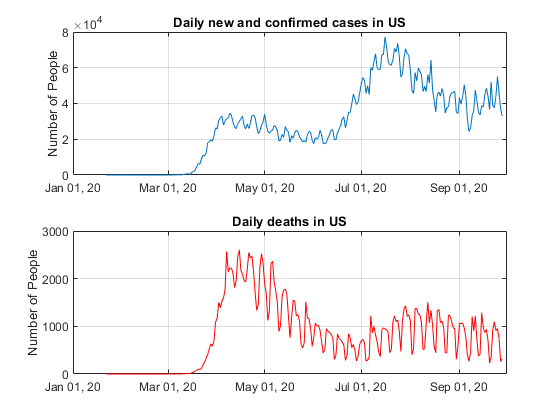

figure;

subplot(2,1,1)
plot(ts2confSelectedCountry)
grid on
title(append('Daily new and confirmed cases in ', selectedCountry))
ylabel('Number of People')

subplot(2,1,2)
plot(ts2deathSelectedCountry,'r')
grid on
title(append('Daily deaths in ', selectedCountry))
ylabel('Number of People')

### Cases in selected country yesterday

confirmedYesterday=datconfSelectedCountry(ncolumns-4)-datconfSelectedCountry(ncolumns-5)

confirmedYesterday = 33037

deathsYesterday=datdeathSelectedCountry(ncolumns-4)-datdeathSelectedCountry(ncolumns-5)

deathsYesterday = 316

### Cumulated cases for the selected country

selectedCountry

selectedCountry = "US"

lastday

lastday = 1×1 cell array
    {'9/28/20'}


SelectedCountryConfirmed=sum(confirmed{confirmed.Country == selectedCountry,ncolumns},1)

SelectedCountryConfirmed = 7148045

SelectedCountryDeaths=sum(deaths{deaths.Country ==selectedCountry,ncolumns},1)

SelectedCountryDeaths = 205072

SelectedCountryRecovered=sum(recovered{recovered.Country ==selectedCountry,ncolumns},1)

SelectedCountryRecovered = 2794608

SelectedCountryActiveCases=SelectedCountryConfirmed-SelectedCountryDeaths-SelectedCountryRecovered

SelectedCountryActiveCases = 4148365

### Case Fatality Rate (CFR)

The case fatality rate (CFR) represents the proportion of cases who eventually die from a disease. Once an epidemic has ended, it is calculated with the formula: deaths / cases.

CFRend = SelectedCountryDeaths / SelectedCountryConfirmed      % multiply the result by 100 to get percentages

CFRend = 0.0287

But while an epidemic is still ongoing, as it is the case with the current novel coronavirus outbreak, this formula is, at the very least, "naïve" and can be "misleading if, at the time of analysis, the outcome is unknown for a non negligible proportion of patients." 

(Methods for Estimating the Case Fatality Ratio for a Novel, Emerging Infectious Disease - Ghani et al, American Journal of Epidemiology).

An alternative method, which has the advantage of not having to estimate a variable, and that is mentioned in the American Journal of Epidemiology study cited previously as a simple method that nevertheless could work reasonably well if the hazards of death and recovery at any time t measured from admission to the hospital, conditional on an event occurring at time t, are proportional, would be to use the formula:

CFRnew = deaths / (deaths + recovered)

CFRnew=SelectedCountryDeaths / (SelectedCountryDeaths + SelectedCountryRecovered)  % multiply the result by 100 to get percentages

CFRnew = 0.0684

## Is there a correlation between the number of infections and the drop in GDP growth on country level?

[Joe Hasell](https://ourworldindata.org/team) recently asked on [https://ourworldindata.org/covid-health-economy](https://ourworldindata.org/covid-health-economy): "Which countries have protected both health and the economy in the pandemic?". He could not find a sign of a health-economy trade-off in his study. Hasell worked with the number of deaths and GDP growth in Q2 2020 per country.

In this part of my analysis, I do more or less the same, but instead of the number of people who died, I took the new and confirmed infections.

He shares some data on the page as well. I took the "economic-decline-in-the-second-quarter-of-2020.csv" file as a base and made some modifications according to my needs. The Excel sheet "GDPvsCOVID19.xlsx" is used to fill it with data from my analysis and further processing.

Definition: Gross Domestic Product (GDP) per capita shows a country's GDP divided by its total population.

% please modify the path to the file according to your own needs
economic=readtable("E:\datasets\COVID19analysis\GDPvsCOVID19.xlsx","Sheet","Tabelle1");

The population data per country are taken from Wolfram Mathematica® 12.1.

**Filling the table with data from Johns Hopkins University for the period "04/01/20" until "06/30/20" = the second quarter 2020**

for i=1:39
    economic.ConfirmedCases2020Q2(i)=sum(confirmed{confirmed.Country ==economic.Entity(i),'7/1/20'})-sum(confirmed{confirmed.Country ==economic.Entity(i),'4/2/20'});
    economic.CasesDividedByPopulation(i)=economic.ConfirmedCases2020Q2(i) / economic.Population(i);
end

economic

economic = 39×7 table
       Entity         Code      GDPgrowth2020Q2_    GDPgrowth2020Q2    Population    ConfirmedCases2020Q2    CasesDividedByPopulation
    _____________    _______    ________________    _______________    __________    ____________________    ________________________

    {'Austria'  }    {'AUT'}          -13.3               -0.133       8.9551e+06               6744                0.00075309       
    {'Belgium'  }    {'BEL'}          -14.5               -0.145       1.1539e+07              46161                 0.0040003       
    {'Bulgaria' }    {'BGR'}           -8.2               -0.082       7.0001e+06               4697                0.00067099       
    {'Canada'   }    {'CAN'}        -13.495             -0.13495     

### Comparison of absolute GDP growth percentages and Infected Population in percent

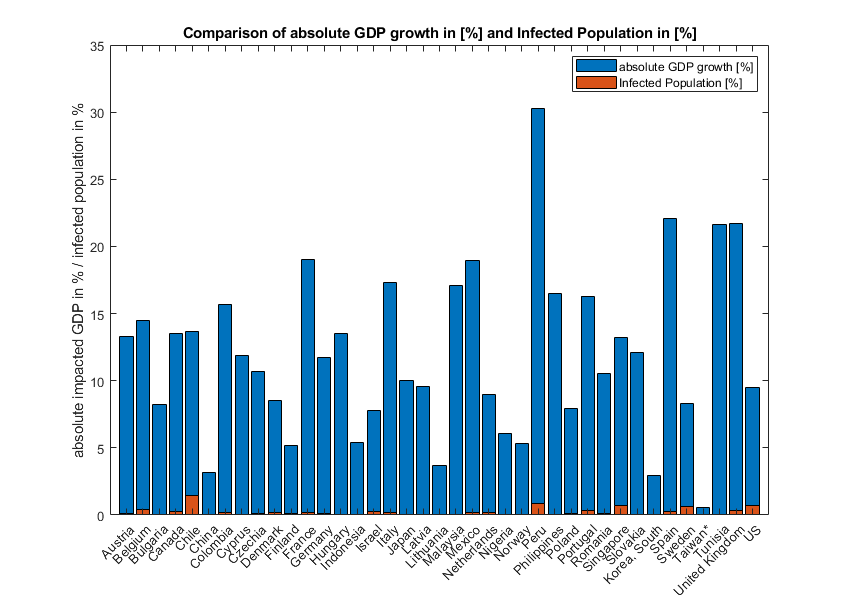


figure;

bar(abs(economic.GDPgrowth2020Q2_))
hold on
bar(economic.CasesDividedByPopulation.*100)
axis([0 40 0 35])
xticks(1:39)
xticklabels({'Austria', 'Belgium','Bulgaria','Canada','Chile','China','Colombia', 'Cyprus' ,'Czechia' ,'Denmark',...
    'Finland','France','Germany','Hungary','Indonesia','Israel','Italy','Japan','Latvia','Lithuania','Malaysia','Mexico',...
    'Netherlands','Nigeria','Norway','Peru','Philippines','Poland','Portugal','Romania','Singapore','Slovakia','Korea, South',...
    'Spain','Sweden','Taiwan*','Tunisia','United Kingdom','US'})
xtickangle(45)

title('Comparison of absolute GDP growth in [%] and Infected Population in [%]')
ylabel('absolute impacted GDP in % / infected population in %')
hold off

legend('absolute GDP growth [%]', 'Infected Population [%]')

% make a bigger plot. values are in pixels.
x0=10;
y0=10;
width=850;
height=600;
set(gcf,'position',[x0,y0,width,height])

### Correlation Coefficient

figure
scatter(economic.CasesDividedByPopulation,economic.GDPgrowth2020Q2,'green')
hold on
mdl = fitlm(economic.CasesDividedByPopulation,economic.GDPgrowth2020Q2)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -0.10134    0.012326    -8.2221    7.1452e-10
    x1              -7.5801      3.3316    -2.2752      0.028782


Number of observations: 39, Error degrees of freedom: 37
Root Mean Squared Error: 0.0621
R-squared: 0.123,  Adjusted R-Squared: 0.099
F-statistic vs. constant model: 5.18, p-value = 0.0288

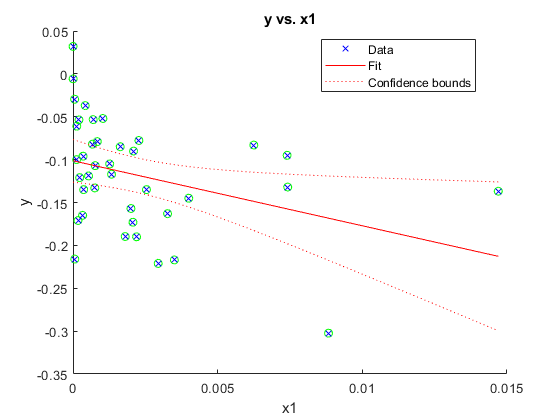

plot(mdl)
hold off

y   »  economic.GDPgrowth2020Q2

x1 »  economic.CasesDividedByPopulation

Fit »  linear regression line

There are several types of correlation coefficients, but the one that is most common is the Pearson correlation (*r*). This measures the strength and direction of the ***linear relationship*** between two variables. It cannot capture nonlinear relationships between two variables and cannot differentiate between dependent and independent variables.

A value of exactly 1.0 means there is a perfect positive relationship between the two variables. For a positive increase in one variable, there is also a positive increase in the second variable. A value of -1.0 means there is a perfect negative relationship between the two variables. This shows that the variables move in opposite directions - for a positive increase in one variable, there is a decrease in the second variable. If the correlation between two variables is 0, there is no linear relationship between them.

[rho,pval] = corr(economic.CasesDividedByPopulation,economic.GDPgrowth2020Q2)

rho = -0.3503

pval = 0.0288

[r,p] = corrcoef(economic.CasesDividedByPopulation,economic.GDPgrowth2020Q2)

r =     1.0000   -0.3503
   -0.3503    1.0000


p =     1.0000    0.0288
    0.0288    1.0000


Hint: The difference between corr(X,Y) and the MATLAB® function corrcoef(X,Y) is that corrcoef(X,Y) returns a matrix of correlation coefficients for two column vectors X and Y. If X and Y are not column vectors, corrcoef(X,Y) converts them to column vectors.

### Conclusion

As expected, the correlation coefficient between column *GDPgrowth2020Q2* and column *CasesDividedByPopulation*, rho = - 0.350, represents a  low negative correlation between the two columns. The corresponding p-value is 0.028. Because the p-value is less than the significance level of 0.05,** it indicates rejection of the null hypothesis that no correlation exists between the two columns**.

In other words, there is a chance for a small correlation regarding the linear relationship between these two columns. Since economics and a virus » outbreak » epidemic » pandemic belong to complex systems with a nonlinear dynamic, we should not be surprised to observe a low correlation. We can assume that many other causes come into play with a stronger impact on GDP growth behavior.